### 0显示视频

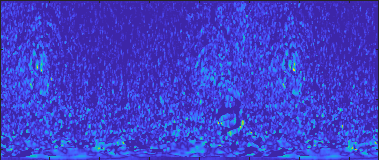

 
path = './data/data1/polHolo/flow/3';
pathes = dir([path,'/*.png']);
for i = 1:height(pathes)
    img = imread([pathes(i).folder,'/',pathes(i).name]);
    img = img(:,:,3);
    img = imresize(img,[160,379]);
    imagesc(img)
    pause(0.1)
end

### 3.1角向精度

 
% 1 角向精度
figure(1)
load('data/R/Angle/angleACC.mat')
imagesc(angleACC)
% 2 采样率
figure(2)
k = 16;
D = [];
d = ceil((k:-1:1)'*10*pi*2);
for i = 0:k-1
    D = [D,d/d(k-i)];
end
D = log(D);
imagesc(D)

### 3.2消融实验

 
% 极坐标RMSE
figure(1)
load('data/R/Abla/data.mat')
RMSE(:,1) = smooth(RMSE(:,1),20);
RMSE(:,2) = smooth(RMSE(:,2),20);
RMSE(:,3) = smooth(RMSE(:,3),20);
RMSE(:,4) = smooth(RMSE(:,4),20);
hold on
plot(RMSE(1:50:501,1));
plot(RMSE(1:50:501,2));
plot(RMSE(1:50:501,3));
plot(RMSE(1:50:501,4));